clearvars
load('MRIdata.mat')

nifti_info.Transform.T'

ans =          0    0.6510         0  -98.1040
    0.7000         0         0  -92.9742
         0         0    0.6510  -96.1088
         0         0         0    1.0000


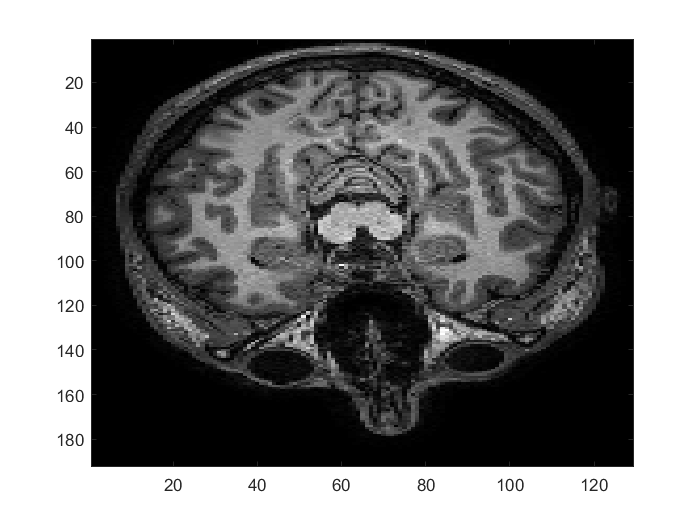

V = niftiread('images/test.nii');
info = niftiinfo('images/test.nii');

imagesc(V(:,:,100)); colormap gray

size(kspace_coils)

ans =    192   129   192     2


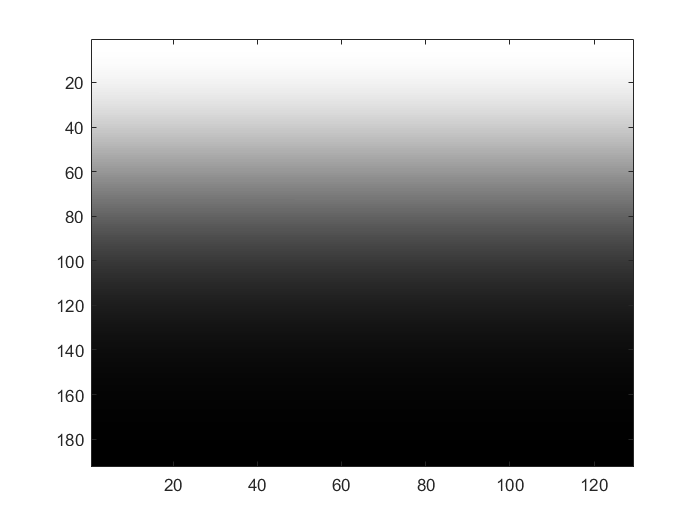

imagesc(coil_sensitivities(:,:,150,1));colormap gray;


imgs_0 = niftiread(strjoin(["images/coilSubsamp_", num2str(0), ".nii"], ''));
imgs_1 = niftiread(strjoin(["images/coilSubsamp_", num2str(1), ".nii"], ''));
sz = size(imgs_0); sz(end+1) = 2;
coil_imgs = zeros(sz);
coil_imgs(:,:,:,1) = imgs_0;
coil_imgs(:,:,:,2) = imgs_1;

sol = SENSE(coil_imgs(:,:,150,:), coil_sensitivities(:,:,150,:))

ys =     49   146


ys =     50   147


ys =     51   148


ys =     52   149


ys =     53   150


ys =     54   151


ys =     55   152


ys =     56   153


ys =     57   154


ys =     58   155


ys =     59   156


ys =     60   157


ys =     61   158


ys =     62   159


ys =     63   160


ys =     64   161


ys =     65   162


ys =     66   163


ys =     67   164


ys =     68   165


ys =     69   166


ys =     70   167


ys =     71   168


ys =     72   169


ys =     73   170


ys =     74   171


ys =     75   172


ys =     76   173


ys =     77   174


ys =     78   175


ys =     79   176


ys =     80   177


ys =     81   178


ys =     82   179


ys =     83   180


ys =     84   181


ys =     85   182


ys =     86   183


ys =     87   184


ys =     88   185


ys =     89   186


ys =     90   187


ys =     91   188


ys =     92   189


ys =     93   190


ys =     94   191


ys =     95   192


ys =     96     1


ys =     97     2


ys =     98     3


ys = 1×2
    99     4


ys = 1×2
   100     5


ys = 1×2
   101     6


ys = 1×2
   102     7


ys = 1×2
   103     8


ys = 1×2
   104     9


ys = 1×2
   105    10


ys = 1×2
   106    11


ys = 1×2
   107    12


ys = 1×2
   108    13


ys = 1×2
   109    14


ys = 1×2
   110    15


ys = 1×2
   111    16


ys = 1×2
   112    17


ys = 1×2
   113    18


ys = 1×2
   114    19


ys = 1×2
   115    20


ys = 1×2
   116    21


ys = 1×2
   117    22


ys = 1×2
   118    23


ys = 1×2
   119    24


ys = 1×2
   120    25


ys = 1×2
   121    26


ys = 1×2
   122    27


ys = 1×2
   123    28


ys = 1×2
   124    29


ys = 1×2
   125    30


ys = 1×2
   126    31


ys = 1×2
   127    32


ys = 1×2
   128    33


ys = 1×2
   129    34


ys = 1×2
   130    35


ys = 1×2
   131    36


ys = 1×2
   132    37


ys = 1×2
   133    38


ys = 1×2
   134    39


ys = 1×2
   135    40


ys = 1×2
   136    41


ys = 1×2
   137    42


ys = 1×2
   138    43


ys = 1×2
   139    44


ys = 1×2
   140    45


ys = 1×2
   141    46


ys = 1×2
   142    47


ys = 1×2
   143    48


ys = 1×2
   144    49


sol = 10×30
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0

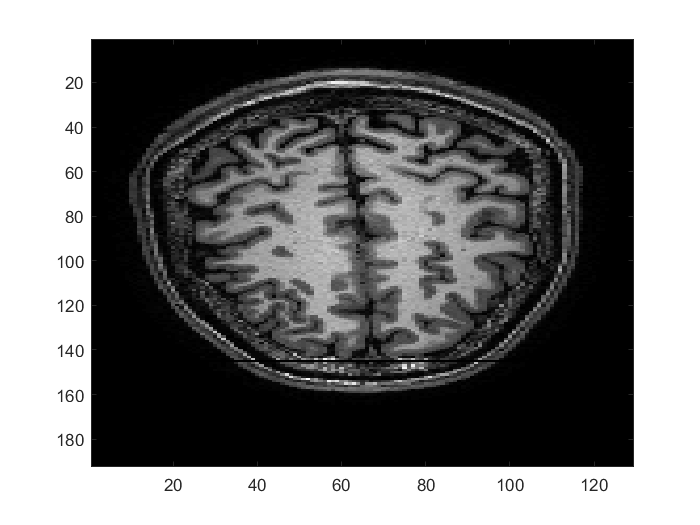

 imagesc(sol); colormap gray

 function out = SENSE(input, sens)
    n = size(sens);
    Ny2 = floor(n(1) / 2);
    Ny4 = floor(Ny2 / 2);
    
    out = zeros(n(1:3));
    
    for img = 1:n(3)
       for y = 1:Ny2
          ys = [y + Ny4, mod(y + Ny4 + Ny2, n(1)) + 1]
          for x = 1:n(2)
              f = squeeze(input(y, x, img, :));
              S = squeeze(sens(ys, x, img, :))';
              sol = S \ f;
              
              out(ys, x, img) = sol;
          end
       end
    end
end